clear all
close all
clc

montage(IMG1N)

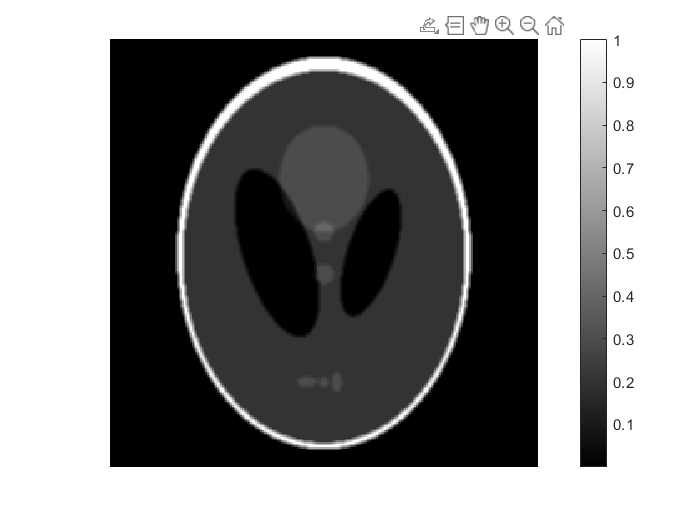

cnr = zeros([1, 15]);
imagesc(IMG1N(:,:,15)), colormap(gray), colorbar, axis('equal','off');
tissueAmask = roipoly;
tissueBmask = roipoly;

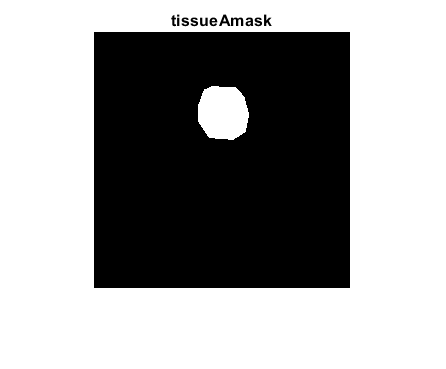

figure
imshow(tissueAmask)
title('tissueAmask')

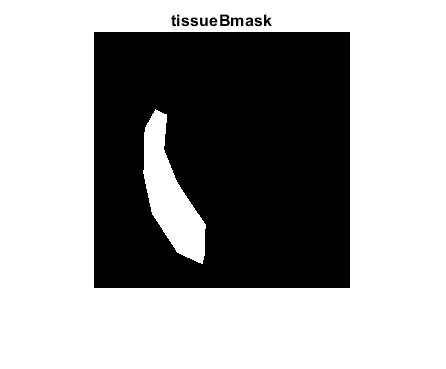

imshow(tissueBmask)
title('tissueBmask')

for k = 1:15
    imgToProcess = IMG1N(:,:,k);
    % extract the mean and SD of the image intensity from within the mask
    roi_mean_diff = abs(mean(imgToProcess(tissueAmask)) - mean(imgToProcess(tissueBmask)));
    cnr(k) = roi_mean_diff / std(double(imgToProcess(tissueAmask)));
end

cnr

cnr =     0.4058    0.7649    1.1535    1.8457    2.9226    4.3798    6.2822    8.5529   11.1065   12.5037   13.4640   13.8820   14.0425   14.1278   14.1466


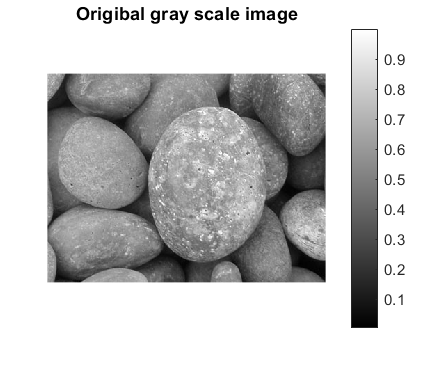

% PART 2 a & b
imagesc(IMG2), colormap(gray), colorbar, axis('equal','off')
title('Origibal gray scale image')

% ----------- PSF h1 -------------
a1 = [1/8,1/4,1/8];
b1 = [1/2,1,1/2];
h1 = b1'*a1;
h1

h1 =     0.0625    0.1250    0.0625
    0.1250    0.2500    0.1250
    0.0625    0.1250    0.0625


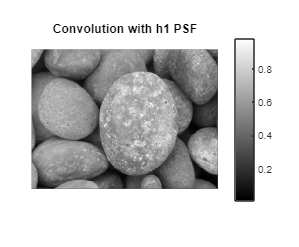

h1 = h1./sum(h1(:)); % scale the PSF 
IMG2a_output = conv2(double(IMG2),h1,'same');
imagesc(IMG2a_output)
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution with h1 PSF')

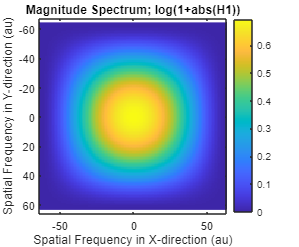


N = 128;
H1 = fftshift(fft2(h1,N,N));
figure(2)
f = [-N/2:1:N/2-1]; 
imagesc(f,f,log(1+abs(H1))); colormap(parula), colorbar, axis('equal') 
xlabel('Spatial Frequency in X-direction (au)')
ylabel('Spatial Frequency in Y-direction (au)')
title('Magnitude Spectrum; log(1+abs(H1))')

% % ----------- PSF h2 -------------
a2 = [1/3,1/3,1/3];
h2 = a2'*a2;
h2

h2 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


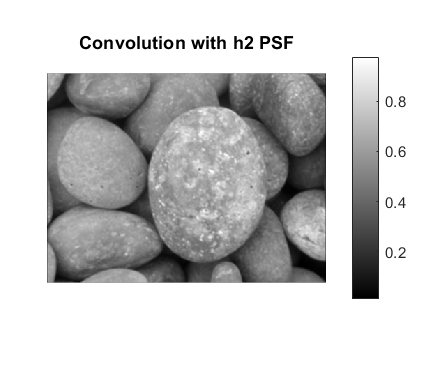

h2 = h2./sum(h2(:)); % scale the PSF 
IMG2b_output = conv2(double(IMG2),h2,'same');
imagesc(IMG2b_output) %[0 255]
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution with h2 PSF')

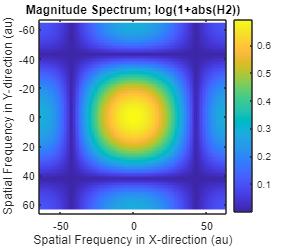


N = 128;
H2 = fftshift(fft2(h2,N,N));
figure(2)
f = [-N/2:1:N/2-1];
imagesc(f,f,log(1+abs(H2))); colormap(parula), colorbar, axis('equal') 
xlabel('Spatial Frequency in X-direction (au)')
ylabel('Spatial Frequency in Y-direction (au)')
title('Magnitude Spectrum; log(1+abs(H2))')

% ----------- PSF h3 -------------
h3 = [0 -1 0; -1 5 -1;0 -1 0]

h3 =      0    -1     0
    -1     5    -1
     0    -1     0


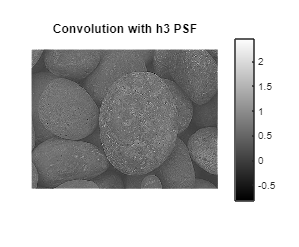

h3 = h3./sum(h3(:)); % scale the PSF 
IMG2c_output = conv2(double(IMG2),h3,'same'); %  crop the output to match the size of the first input argument.
imagesc(IMG2c_output) %[0 255]
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution with h3 PSF')

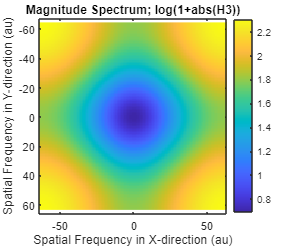


N = 128;
H3 = fftshift(fft2(h3,N,N));
figure(2)
f = [-N/2:1:N/2-1];
imagesc(f,f,log(1+abs(H3))); colormap(parula), colorbar, axis('equal') 
xlabel('Spatial Frequency in X-direction (au)')
ylabel('Spatial Frequency in Y-direction (au)')
title('Magnitude Spectrum; log(1+abs(H3))')

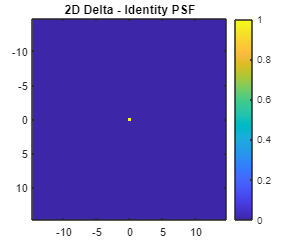

%Part 2c Identity PSF
[Nr,Nc] = size(IMG2);
N = floor(min([Nr,Nc]/10));
hi = -(N-1)/2:1:(N-1)/2;
hdelta = zeros(65,65);
hdelta((end+1)/2,(end+1)/2) = 1;
% hdiff = hdelta-h2D;
imagesc(hi,hi',hdelta), colormap(parula), colorbar 
title('2D Delta - Identity PSF')

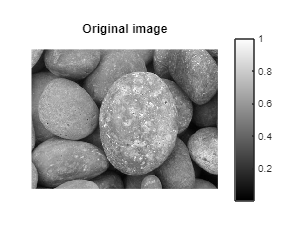


% --- Prove -----
IMG2d_output = conv2(double(IMG2),hdelta,'same'); %  crop the output to match the size of the first input argument.
imagesc(IMG2)
axis('equal'), colormap(gray), colorbar, axis('off')
title('Original image')

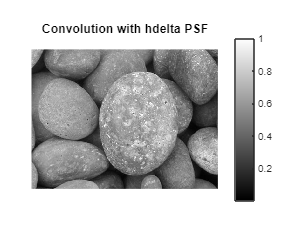

imagesc(IMG2d_output) %[0 255]
axis('equal'), colormap(gray), colorbar, axis('off')
title('Convolution with hdelta PSF')

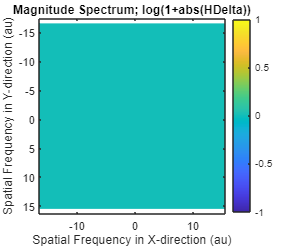


%Part 2d FT of Identity PSF
N = 32;
HDelta = fftshift(fft2(hdelta,N,N));
figure(2)
f = [-N/2:1:N/2-1];
imagesc(f,f,log(1+abs(HDelta))); colormap(parula), colorbar, axis('equal') 
xlabel('Spatial Frequency in X-direction (au)')
ylabel('Spatial Frequency in Y-direction (au)')
title('Magnitude Spectrum; log(1+abs(HDelta))')